clear
tic
close all
load direction_data.mat
data = direction_data{60}.document_properties.stimulus_tuningcurve.response_mean;
ang = direction_data{60}.document_properties.stimulus_tuningcurve.independent_variable_value;
toc

Elapsed time is 0.127316 seconds.


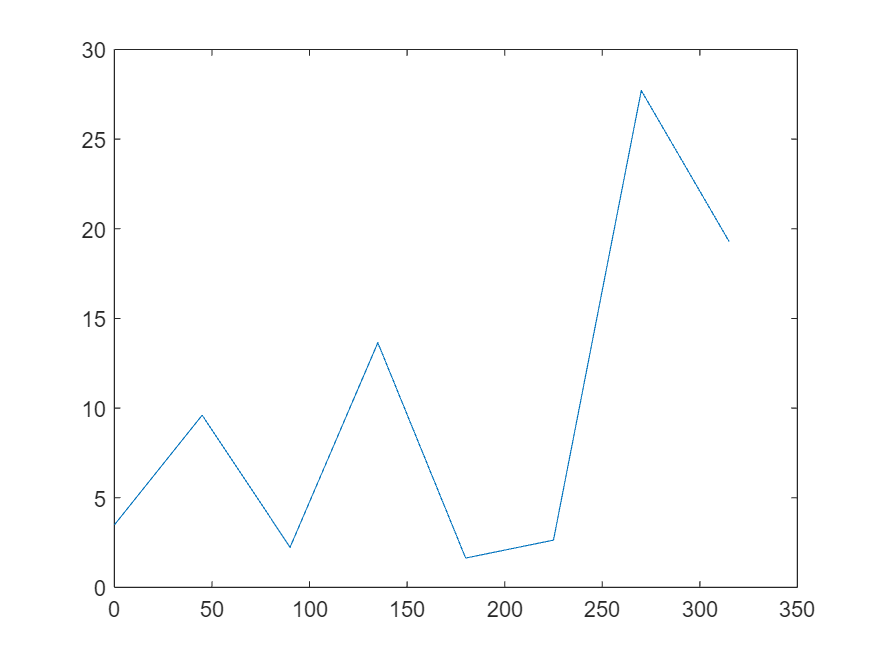

plot(ang,data)

I = struct('Rp',logspace(log10(.5),log10(150),100), ...
    'Op',0:5:359, ...
    'Alpha',linspace(0,1,50), ...
    'Sig',logspace(log10(5),log10(90),20), ...
    'Noise_Sig',linspace(.05,15,25));

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

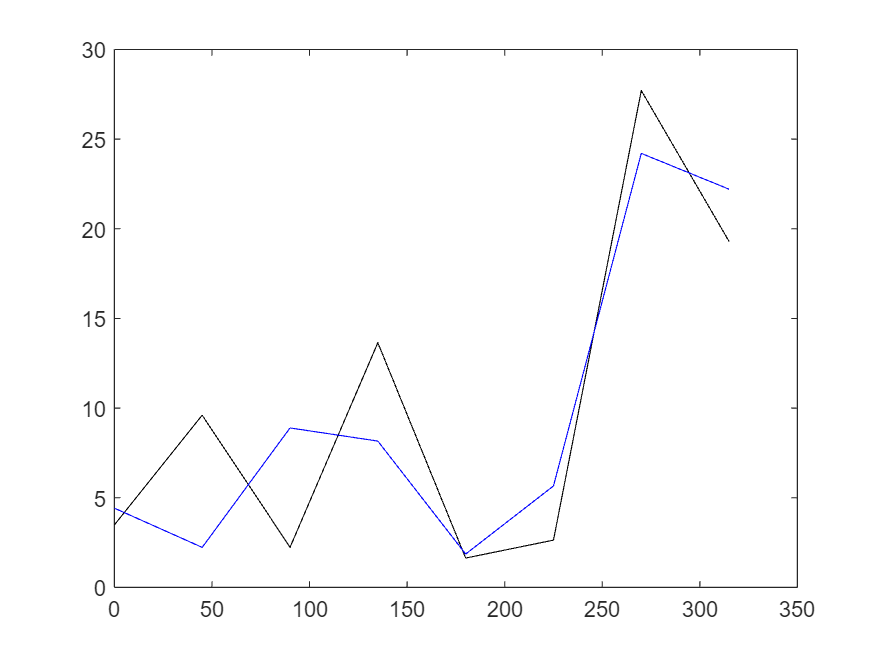

tic;
Lik = bayes_grid_function(I,data,ang);

toc;

Elapsed time is 228.736666 seconds.


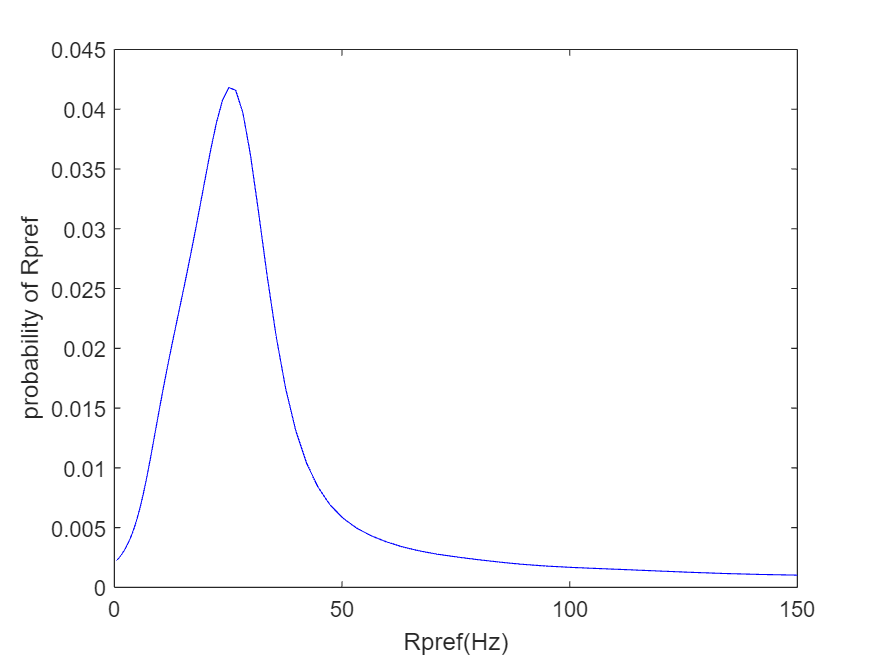

[M,ind] = max(Lik.Lik,[],'all'); % get maximum liklihood of parameters value and get the index of parammatlab:helpview('matlab','error_nomem')eters
[i,j,k,h,n] = ind2sub(size(Lik.Lik),ind);

DI = (1 - I.Alpha)./(1+I.Alpha);
LDI = Lik.Alpha;

plot(I.Rp,Lik.Rp,'b'),% Rp
xlabel("Rpref(Hz)"), 
ylabel("probability of Rpref"),

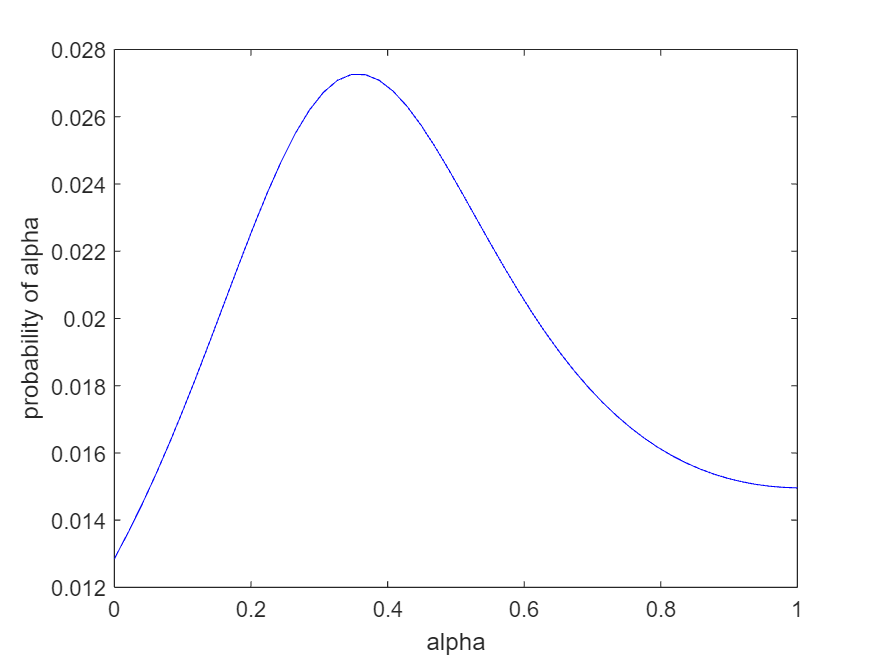


plot(I.Alpha,Lik.Alpha,'b'),% Rn
xlabel("alpha"),
ylabel("probability of alpha"),

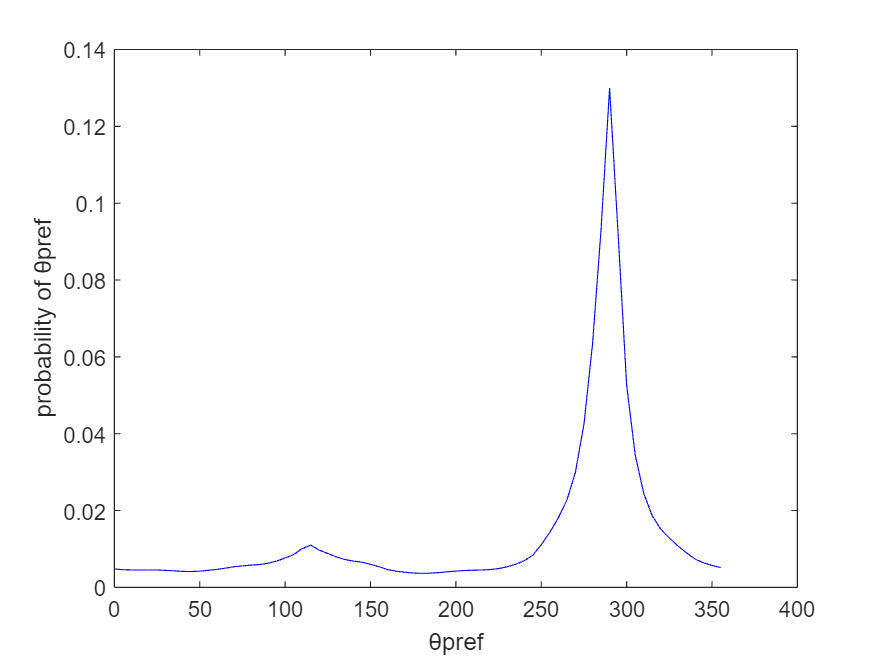


plot(I.Op,Lik.Op,'b'),
xlabel("θpref"),
ylabel("probability of θpref"),

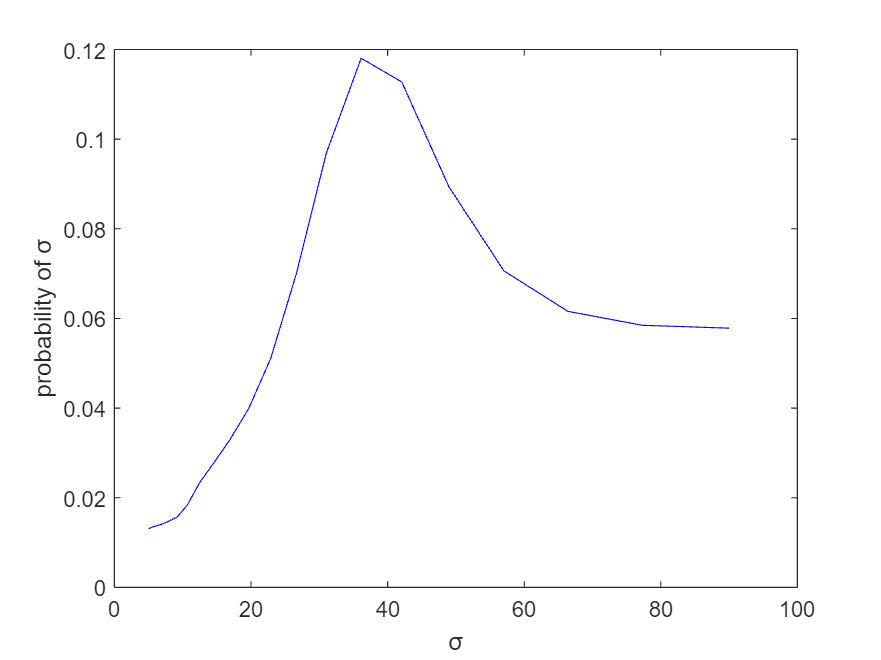


plot(I.Sig,Lik.Sig,'b'),
xlabel("σ"),
ylabel("probability of σ"),

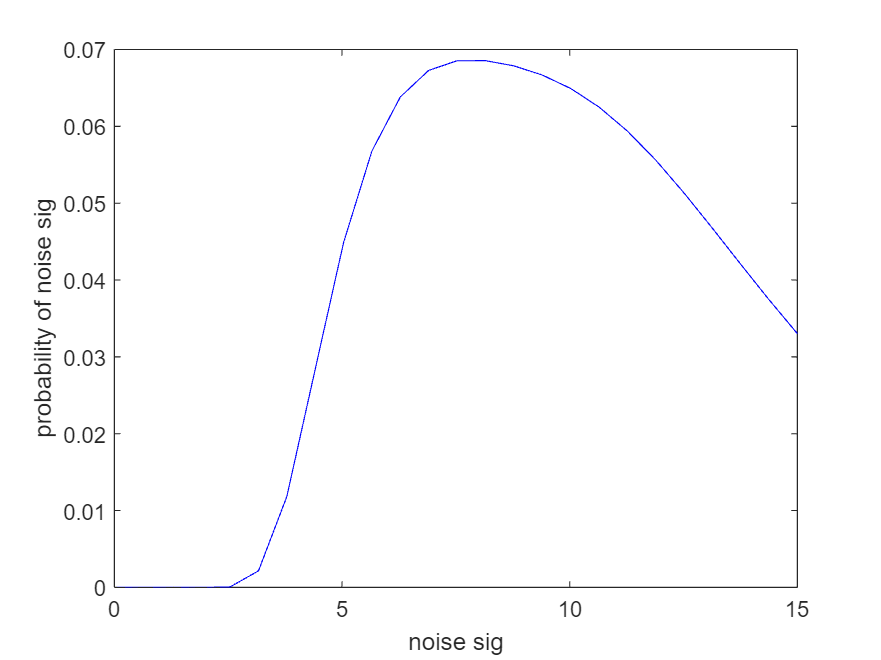


plot(I.Noise_Sig,Lik.Noise_Sig,'b'),
xlabel("noise sig"),
ylabel("probability of noise sig"),

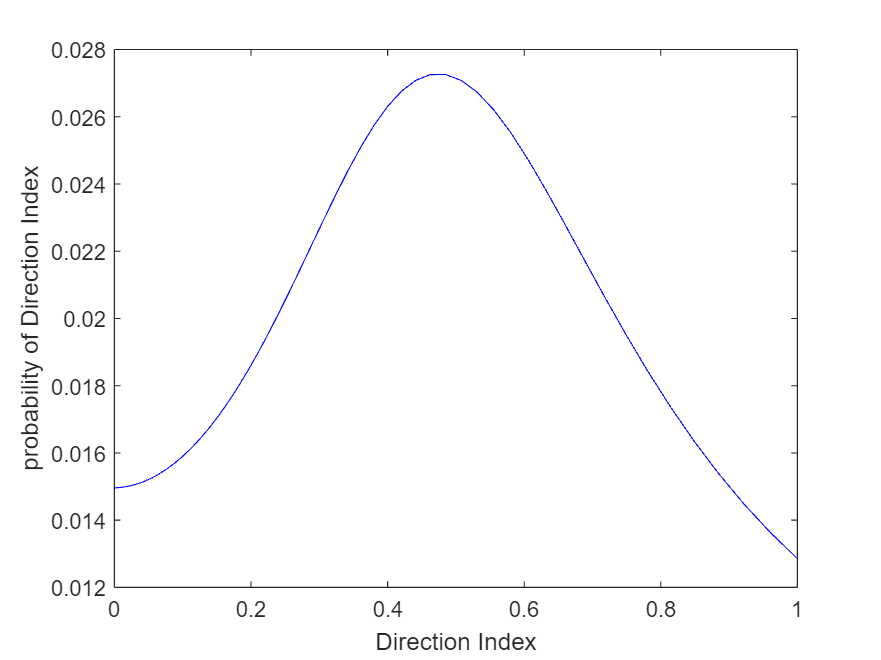


plot(DI,LDI,'b'),
xlabel("Direction Index"),
ylabel("probability of Direction Index"),